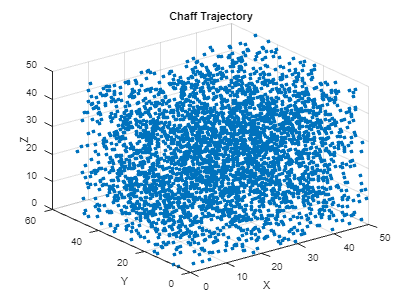

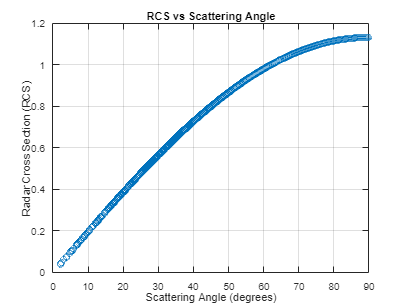

%Code to model 6DOF primarily using the paper: 
%https://www.researchgate.net/publication/327064480_Experimental_and_numerical_study_of_chaff_cloud_kinetic_performance_under_the_impact_of_high_speed_airflow
%implementation of RCS from: 'Absoprtion and scattering of light by small
%particles', Bohren and Huffman (1988)

main()

function main()
    % Initialising parameters
    theta = pi/2; %pitch angle (radians)
    Psi_s = pi/3; %yaw? angle (radians)
    zeta = pi; % (radians)
    psi = pi/2; %(radians)
    E_wave = [1, 0, 0]; %Incident EM wave direction coming from x-direction

    % Unit vectors
    n_d = [(-sin(zeta)*cos(psi)), (cos(zeta)), (sin(zeta)*sin(psi))]; %unit vector of 
    n_v = [(cos(theta)*cos(psi)), sin(theta), (-cos(theta)*sin(psi))]; %unit vector of velocity 
    n_y = cross(n_v, cross(n_v,n_d) * dot(n_v,n_d)); %unit vector of lift 
    n_y = n_y / norm(n_y);

    gamma_s = -asin(((n_v(3)*n_y(1)) - (n_v(1)*n_y(3))*n_y(2)) / (sqrt((n_v(1))^2+(n_v(3))^2) * abs(n_y(2)))); % roll angle (radians)ans)

    % Constants
    m = 5.59; %Mass of chaff fibre (grams)
    g = 9.81; %accleration due to gravity (ms^2)
    rho = 0.7364; %atmospheric density (assumed constant) (kg/m^3)
    aOne = 1.5; %Distance impact factor
    fValue = 0.1;  %Proportionality coefficient
    dt = 0; %Time step
    maxTime = 410; %Final time of the simulation
    numberOfChaff = 3900; %Number of chaff fibres
    sizeOfChaff = 15; %Size of chaff on the graph
    V = 30; %Size of chaff on the graph
    radius = 0.03; %Radius of chaff
    aircraftMass = 8500;     % kg
    load_factor = 1.3;           % dimensionless
    aircraftWingspan = 25;                      % m (wingspan)
    aircraftSpeed = 800;             % m/s
     
    S = 4*pi*radius^2; %area of chaff (m^2) %want to treat like a sphere

    steps = maxTime / dt;

    rcore = 0.5;                 % vortex core radius [m]
    % Lift and circulation
    L = load_factor * aircraftMass * g;
    Gamma = L / (rho * aircraftWingspan * aircraftSpeed);  % Circulation [m^2/s]

    % Example: two vortices
    vortex_start_1 = [-2E8, 0, 0]; % left wingtip
    vortex_end_1   = [-2E8, 0, -10E5]; % trailing downwards behind aircraft
    vortex_start_2 = [2E8, 0, 0];  % right wingtip
    vortex_end_2   = [2E8, 0, -10E5];% left and right wingtip
    Gamma_j = [-Gamma, Gamma];

    % Call the main function
    [inci_array, rcs_array, rcs_normalized] = kinematic_equations(gamma_s, aOne, fValue, 0.52, 0.82, dt, maxTime, m, g, numberOfChaff, rho, S, sizeOfChaff, V, steps, zeta, psi, E_wave, radius,Gamma_j,vortex_start_1,vortex_end_1,vortex_start_2,vortex_end_2);

    % Plot RCS vs Angle
    figure;
    plot(rad2deg(inci_array), rcs_normalized, 'o');
    xlabel('Scattering Angle (degrees)');
    ylabel('Radar Cross Section (RCS)');
    title('RCS vs Scattering Angle');
    grid on;
end

% Subfunction 1
function [cX, cY] = calculateAerodynamicInterferenceImpactFactors(aOne, fValue, cXPrime, cYPrime)  %Function calculates cX and cY due to the constants f and a1 from paper
    cX = cXPrime * (1 - aOne);
    cY = cYPrime * fValue * (1 - aOne);
    %a1 is distance impact factor and f is proportionality coefficient
end

% Subfunction 2
function [inci_array, rcs_array, rcs_normalized] = kinematic_equations(gamma_s, aOne, fValue, cXPrime, cYPrime, dt, maxTime, m, g, numberOfChaff, rho, S, sizeOfChaff, V, steps, zeta, psi, E_wave, radius,Gamma_j,vortex_start_1,vortex_end_1,vortex_start_2,vortex_end_2)

    [cX, cY] = calculateAerodynamicInterferenceImpactFactors(aOne, fValue, cXPrime, cYPrime);
    xValues = [];
    yValues = [];
    zValues = [];

    inci_array = zeros(1, numberOfChaff);
    rcs_array = zeros(1, numberOfChaff);

    for i = 1:numberOfChaff
        x = rand()*50; y = rand()*50; z = rand()*50;
        theta = pi; 
        PsiS = pi;
        V_local = V;
        zeta_i = 2*pi*rand();  % Random initial zeta for each chaff
        psi_i = 2*pi*rand();

        for t = 0:dt:maxTime
            n_d = [(-sin(zeta)*cos(psi)), cos(zeta), sin(zeta)*sin(psi)];
            n_v = [(cos(theta)*cos(psi)), sin(theta), (-cos(theta)*sin(psi))];
            n_y = cross(n_v, cross(n_v,n_d) * dot(n_v,n_d));
            n_y = n_y / norm(n_y);

            gamma_s = -asin(((n_v(3)*n_y(1)) - (n_v(1)*n_y(3))*n_y(2)) / ...
                (sqrt(n_v(1)^2 + n_v(3)^2) * abs(n_y(2))));

            X = 0.5 * cX * rho * V_local^2 * S; %Calculates drag
            Y = 0.5 * cY * rho * V_local^2 * S; %Calculates lift

            dV = ((-X - m*g*sin(theta))/m)*dt; %Change in velocity at each time step
            dTheta = ((Y*cos(gamma_s) - m*g*cos(theta))/(m*V_local))*dt; %Change in theta at each time step
            dPsiS = ((-Y*sin(gamma_s))/(m*V_local*cos(theta)))*dt; %Change in Psi at each time step

            V_local = max(1, min(300, V_local + dV));  % clamp velocity and update the value
            theta = theta + dTheta; %Update the theta value
            PsiS = PsiS + dPsiS; %update the psi value
            r_chaff = [xValueCurrent, yValueCurrent, zValueCurrent];
            v1 = vortex_induced_velocity_3D(r_chaff, vortex_start_1, vortex_end_1, Gamma_j(1));
            v2 = vortex_induced_velocity_3D(r_chaff, vortex_start_2, vortex_end_2, Gamma_j(2));
            v_ind_total = v1 + v2;
            %Uses these new values of V, theta and Psi to find the change in the coordinate

            dx = (V_local * cos(theta) * cos(PsiS) +v_ind_total(1))* dt;
            dy = (V_local * sin(theta)+v_ind_total(2) )* dt;
            dz = (-V_local * cos(theta) * sin(PsiS)+v_ind_total(3)) * dt;

            x = x + dx;
            y = y + dy;
            z = z + dz;
        end

        % Store coordinates
        xValues(end+1) = x;
        yValues(end+1) = y;
        zValues(end+1) = z;

        % Use final position to compute n_d direction
        positionVec = [x, y, z];
        if norm(positionVec) == 0
            n_d = [1, 0, 0]; % fallback to E_wave direction
        else
            n_d = positionVec / norm(positionVec);
        end

        % Compute scattering angle
        inci = acos((dot(E_wave, n_d) / norm(E_wave)*norm(n_d)));


        % RCS calculation
        rcs = pi * (radius)^2 * sin(inci);

        inci_array(i) = inci; %store the values for incident angle
        rcs_array(i) = rcs; %store the values for rcs

        % Normalize RCS 
        lambda = 5e-2; % Example wavelength (1.5cm) - adjust for desiredS radar
        rcs_normalized = rcs_array / (lambda^2);% Normalize by wavelength squared
    end

    % 3D scatter plot
    figure;
    scatter3(xValues, yValues, zValues, sizeOfChaff, 'filled');
    title('Chaff Trajectory');
    xlabel('X'); ylabel('Y'); zlabel('Z');
    grid on;
end

%Calculated induced velocity due to vortices
function v_ind = vortex_induced_velocity_3D(r, vortex_start, vortex_end, Gamma)

    epsilon = 1e-6; % To prevent singularity

    R1 = r - vortex_start;
    R2 = r - vortex_end;
    R0 = vortex_end - vortex_start;

    cross_R1_R2 = cross(R1, R2);
    norm_cross = norm(cross_R1_R2)^2;

    if norm_cross < epsilon
        v_ind = [0, 0, 0];
        return;
    end

    numerator = dot(R0, (R1 ./ norm(R1) - R2 ./ norm(R2)));
    v_ind = (Gamma / (4 * pi * norm_cross)) * cross_R1_R2 * numerator;
end

